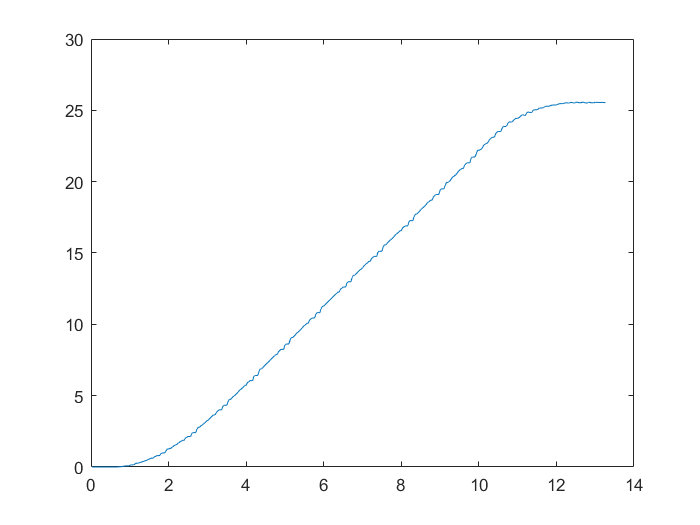

fileName = "../Data/Tracker/07112022-09.csv";
data = readtable(fileName);

tPos = table2array(data(:,1));
x = table2array(data(:,2));
y = table2array(data(:,3));
dist = sqrt((x-x(1)).^2 + (y-y(1)).^2);
startIndex = find(dist < .001, 1, "last");
endIndex = floor(startIndex + numel(tPos)*.75);
plot(tPos,dist);

F = @(x, t) heaviside(t-x(3)).*(-x(1).*x(2)+x(2).*(t-x(3))+x(1).*x(2).*exp(-(t-x(3))./x(1)));
x0 = [1 1 2.5];
x = lsqcurvefit(F,x0,tPos(startIndex:endIndex), dist(startIndex:endIndex)-dist(startIndex))


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x =     1.0806    2.7463    0.8573


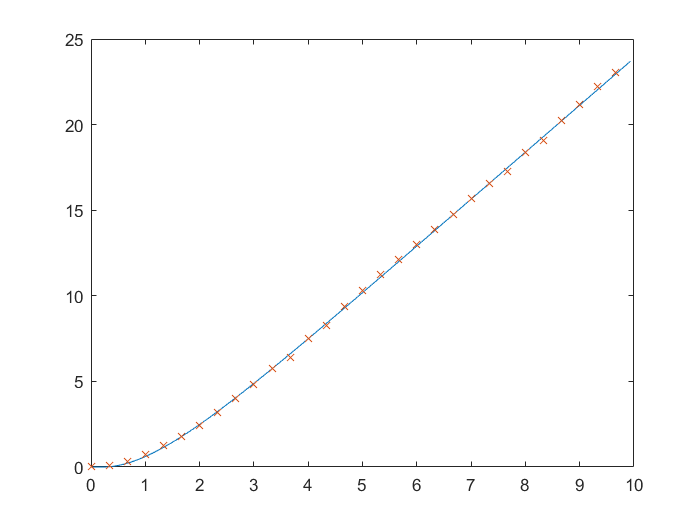

plot(tPos(startIndex:endIndex)-tPos(startIndex), F(x,tPos(startIndex:endIndex)), tPos(startIndex:10:endIndex)-tPos(startIndex), dist(startIndex:10:endIndex)-dist(startIndex), 'x')